% simulatePBS_scalar.m
% Simulate four “pads” in a PBS‐filled petri dish
% using the frequency‐domain scalar PDE approach.

%% 1) Parameters
%f1    = 2000;             % stimulation frequency [Hz]
%f2    = 2010;
%omega1 = 2*pi*f1;            % angular frequency [rad/s]
%omega2 = 2*pi*f2 
R     = 45;             % dish radius [mm]
re    = 1e-1;              % pad radius [mm]
sigma = 1.5;               % PBS conductivity [S/m]
eps0  = 8.8541878128e-12;  % vacuum permittivity [F/m]

% Voltages of StimSignal (amplitude [V])
A = [5, 5, 0, 0];
% Phase of StimSignal (phase [rad])
phi = [0, 0, 0, 0];

%Impedances of Acq Circuit
Rs = 60e3;              % 60 kΩ
Ze = 2e6;               % 2 MΩ
% Effective pad voltages after going through the resistance
Vpad = A  %(Ze/(Rs+Ze));  

Vpad =      5     5     0     0


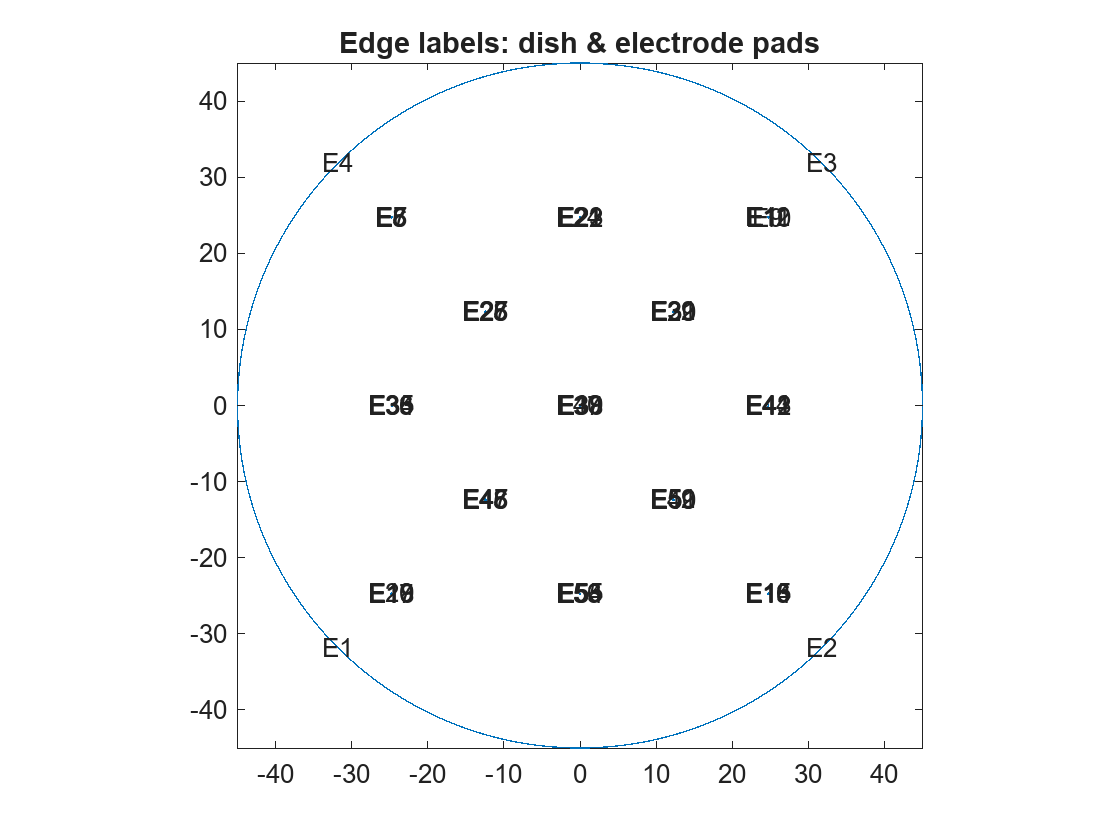

% Currents flowing *through* the series resistor (and into the Electrode and PBS)
%Iseries = A./(Rs+Ze);  
% (same as Vpad/Ze)

% Raw pad positions from bottom‐left in cm
dishCtr_cm  = [4.5, 4.5];          % dish center in cm

pads_cm_raw = [2.025, 6.975;   % Electrode (Diagram -- A)
               6.975, 6.975;   % Electrode (Diagram -- B)
               6.975, 2.025;   % Electrode (Diagram -- C)
               2.025, 2.025;   % Electrode (Diagram -- D)
               4.50, 6.975;   % Measuring Point -- 3
               3.26, 5.73;   % Measuring Point -- 4
               5.73, 5.73;   % Measuring Point -- 5
               2.025, 4.50;   % Measuring Point -- 6
               4.50, 4.50;   % Measuring Point -- 7
               6.975, 4.50;   % Measuring Point -- 8
               3.26, 3.26;   % Measuring Point -- 9
               5.73, 3.26;   % Measuring Point -- 10
               4.50, 2.025];   % Measuring Point -- 11

% Recenter to dish‐center and convert to meters
pads_cm_centered = pads_cm_raw - dishCtr_cm;
centers = pads_cm_centered * 10;  % 4×2 array [mm]

%% 2) Build geometry: big dish minus 4 pad-holes
model2 = createpde(1);  % scalar PDE

% 2a) Prepare decsg inputs
N = size(centers,1);
gd = [1;0;0;R];
for k=1:N
    gd(:,end+1) = [1; centers(k,1); centers(k,2); re];
end

names = cell(1,N+1);
names{1} = 'C1';
for k=1:N
    names{k+1} = sprintf('E%d',k);
end

L = max(cellfun(@length,names));
ns = repmat(' ',L,N+1);
for k=1:N+1
    nm = names{k};
    ns(1:length(nm),k) = nm;
end

sf = names{1};
for k=2:N+1
    sf = [sf '-' names{k}];
end

% 2b) Import geometry
[g,bt] = decsg(gd,sf,ns);
geometryFromEdges(model2,g);

% — 2c) Quick plot to read edge IDs (outer dish + each pad) —
figure;
pdegplot(model2,'EdgeLabels','on');
axis equal tight;
title('Edge labels: dish & electrode pads');

% pre-3) Group the edges for each pad (dish edges are 1:4, pads are 5:8,9:12,…)
padEdges = cell(1,N);
for k=1:N
    padEdges{k} = (4*k+1) : (4*k+4);
end
padEdges

padEdges = 1×13 cell array
    {[5 6 7 8]}    {[9 10 11 12]}    {[13 14 15 16]}    {[17 18 19 20]}    {[21 22 23 24]}    {[25 26 27 28]}    {[29 30 31 32]}    {[33 34 35 36]}    {[37 38 39 40]}    {[41 42 43 44]}    {[45 46 47 48]}    {[49 50 51 52]}    {[53 54 55 56]}


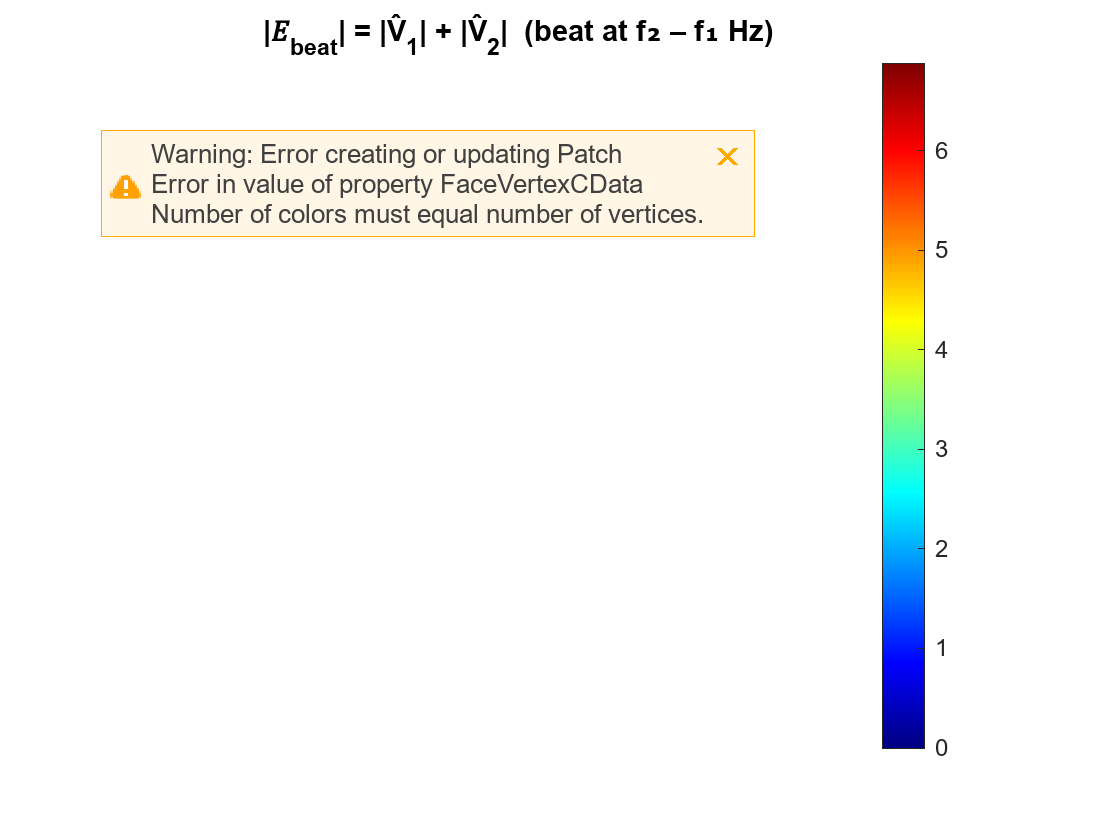

%% --- 3–5) Two‐frequency solves + envelope ---

% Frequencies [Hz]
f1 = 1000;
f2 = 1010;
freqs = [f1, f2];

% Preallocate result storage
sol = cell(1,2);

% We’ll reuse these from your script:
%   g              = your geometry from decsg
%   padEdges       = cell array, padEdges{k} = edge IDs for pad k
%   hGlobal, hPad, electrodeEdges = your mesh parameters

for ii = 1:2
    % Select this frequency
    f_here = freqs(ii);
    omega  = 2*pi*f_here;
    
    % 3) Build a fresh scalar PDEModel for this solve
    m    = createpde(1);
    geometryFromEdges(m, g);
    
    % 4) Boundary conditions for this frequency
    %    pad 1 @ f₁; pad 2 @ f₂
    %    ground pad (e.g. pad 4) always at 0 V
    %    all other pads at 0 V by default (no BC → insulated)
    if ii == 1
      % f₁ solve: pad 1 driven, pad 2,4 grounded
      cfg = {
        1, Vpad(1), phi(1);   % pad 1 @ Vpad(1)∠phi(1)
        %2, 0       , 0;       % pad 2 @ 0 V
        3, 0       , 0; %3
        4, 0       , 0;   %4    % pad 4 (ground) @ 0 V
      };
    else
      % f₂ solve: pad 2 driven, pad 1,4 grounded
      cfg = {
        %1, 0       , 0;       % pad 1 @ 0 V
       2, Vpad(2), phi(2);   % pad 2 @ Vpad(2)∠phi(2)
        3, 0, 0;              %3
        4, 0       , 0;       % pad 4 (ground) @ 0 V
      };
    end
    
    % Apply exactly one Dirichlet BC per entry in cfg
    for k = 1:size(cfg,1)
      padIdx = cfg{k,1};
      amp    = cfg{k,2};
      phs    = cfg{k,3};
      Vk     = amp * exp(1j*phs);
      applyBoundaryCondition(m, ...
        'dirichlet', ...
        'Edge', padEdges{padIdx}, ...
        'u',     Vk);
    end
    
    % 3) PDE coefficients: c = σ + jωε₀
    cval = sigma + 1j*omega*eps0;
    specifyCoefficients(m, 'm',0,'d',0,'c',cval,'a',0,'f',0);
    
    % 5) Mesh with local refinement on electrode edges
    hGlobal = 1;
    hPad = 2e-1;
    generateMesh(m, ...
      'Hmax' , hGlobal, ...
      'Hedge', {electrodeEdges, hPad});
    
    % Solve for this frequency
    sol{ii} = solvepde(m);
end

% Extract the two phasor solutions
V1h = sol{1}.NodalSolution;
V2h = sol{2}.NodalSolution;

% Build the envelope phasor
VenvMag = abs(V1h) + abs(V2h);

% Now you can plot:
%   abs(sol{1}.NodalSolution)  → |V̂| at 2 kHz
%   abs(sol{2}.NodalSolution)  → |V̂| at 2.01 kHz
%   VenvMag                     → envelope amplitude

% e.g. replace your old envelope‐plot with:
figure;
patch('Faces',mesh.Elements', ...
      'Vertices',mesh.Nodes', ...
      'FaceVertexCData',VenvMag, ...
      'FaceColor','interp','EdgeColor','none');
axis equal tight off; colormap(jet); colorbar;
title('|𝐸_{beat}| = |V̂_1| + |V̂_2|  (beat at f₂ – f₁ Hz)');

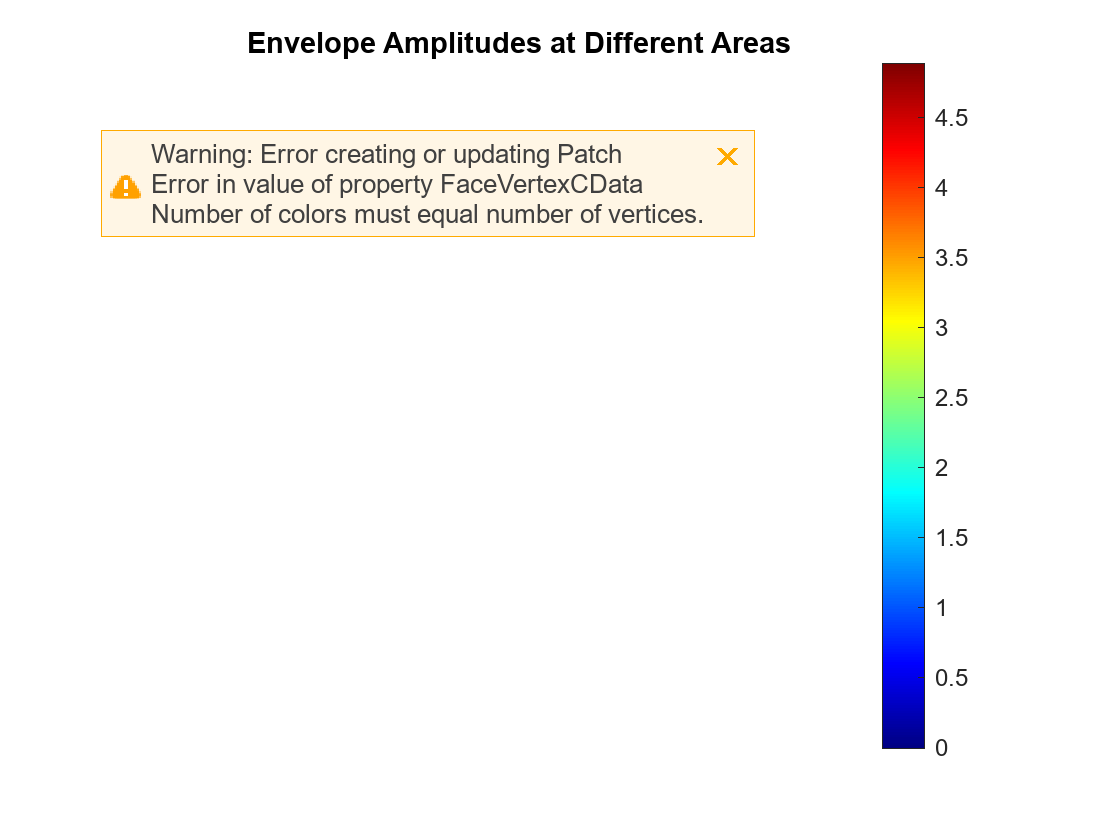

% phasor magnitudes from your two solves
V1mag = abs(sol{1}.NodalSolution);
V2mag = abs(sol{2}.NodalSolution);

% beat–amplitude (half peak‐to‐peak envelope)
Abeat = min(V1mag, V2mag);
% or full peak‐to‐peak:  2*Abeat
PP_beat = 2*Abeat;

% plot the beat amplitude map
figure;
patch('Faces'          , mesh.Elements', ...
      'Vertices'       , mesh.Nodes', ...
      'FaceVertexCData', PP_beat, ...
      'FaceColor'      , 'interp', ...
      'EdgeColor'      , 'none');
axis equal tight off;
colormap(jet);
colorbar;
title('Envelope Amplitudes at Different Areas');

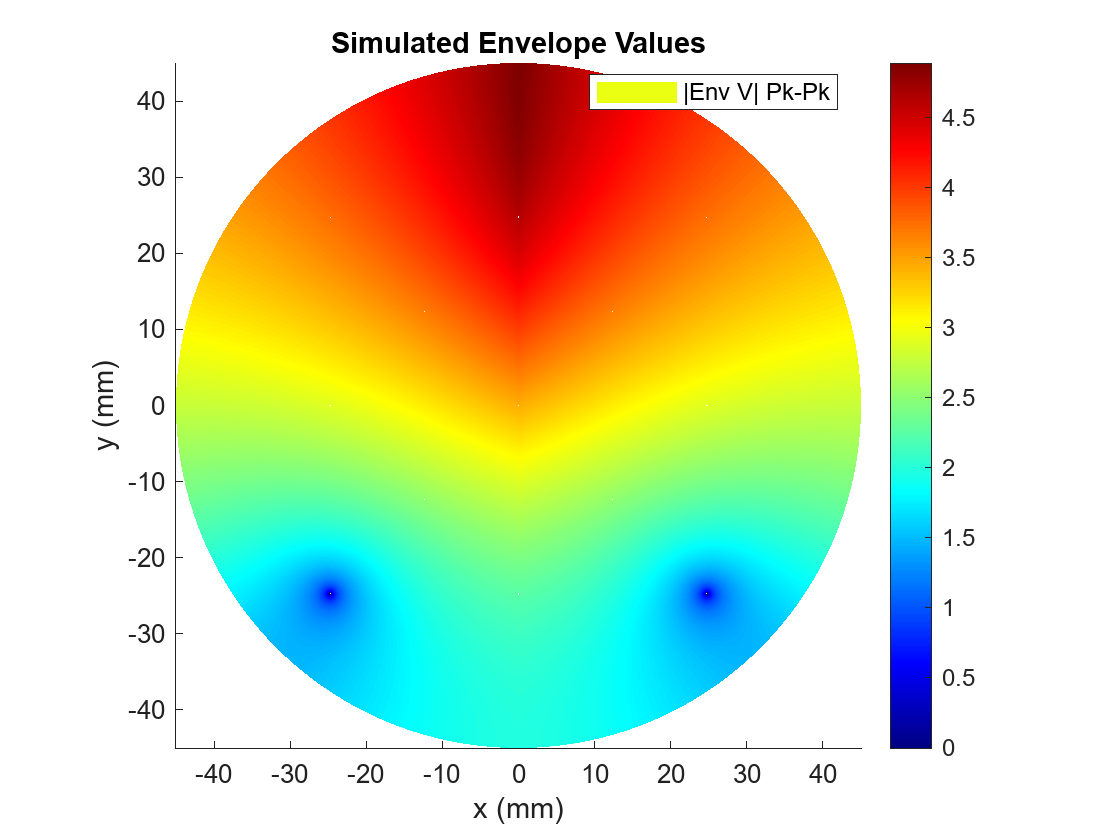

figure;
pdeplot(m, ...
  'XYData',PP_beat, ...
  'Mesh','off');
axis equal tight; colormap(jet);
title('Simulated Envelope Values');
xlabel('x (mm)'); ylabel('y (mm)');
legend('|Env V| Pk-Pk','Location','best');

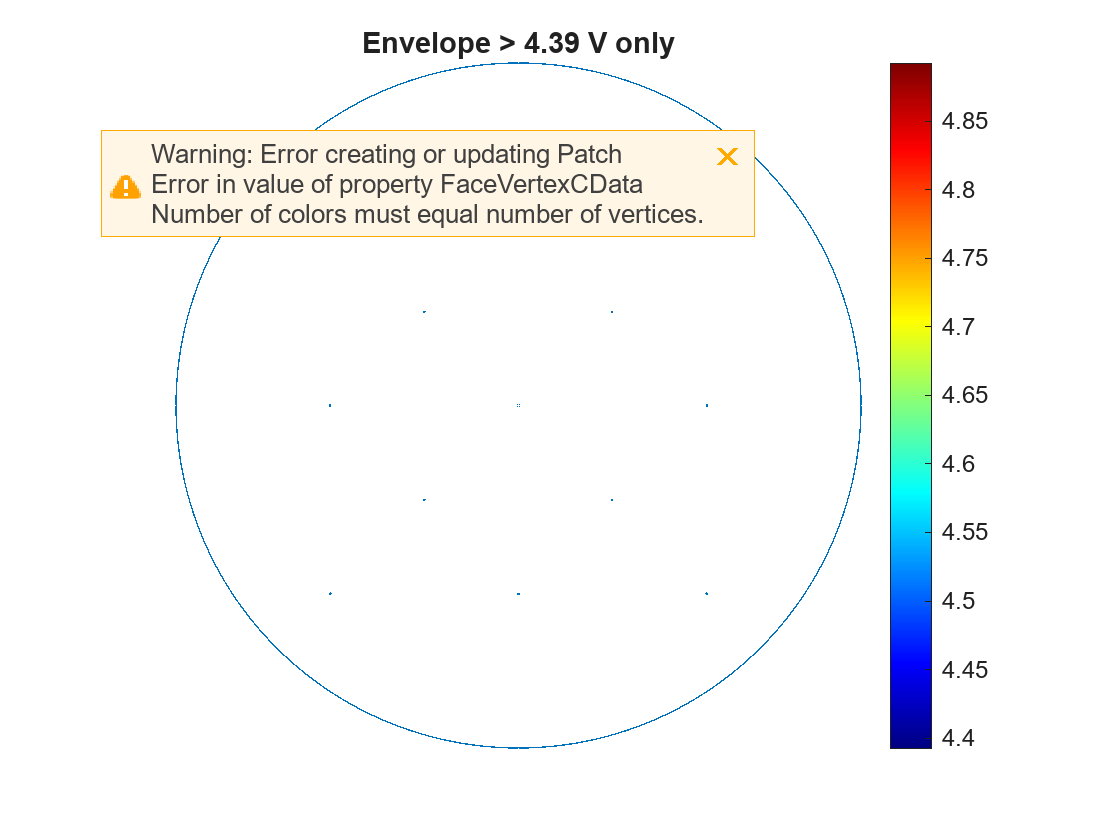


% --- 1) Your masked‐patch code ---
th = max(PP_beat) - 0.5;
C  = PP_beat;
C(C < th) = NaN;

figure; hold on;
patch( ...
   'Faces'          , mesh.Elements', ...
   'Vertices'       , mesh.Nodes'   , ...
   'FaceVertexCData', C             , ...
   'FaceColor'      , 'interp'      , ...
   'EdgeColor'      , 'none'        ...
);
colormap(jet); colorbar;
title(sprintf('Envelope > %.2f V only', th));

% --- 2) Overlay entire dish+pad outline ---
pdegplot(model2, 'FaceAlpha',0, 'EdgeLabels','off');


axis equal tight off;
hold off;

x0 = 20.25; y0 = 45;
% --- find the index of the mesh node closest to (x0,y0) ---
nodeIdx = findNodes(mesh,'nearest',[x0; y0]);
Abeat_node = min(abs(sol{1}.NodalSolution(nodeIdx)), ...
                 abs(sol{2}.NodalSolution(nodeIdx)));
PPbeat_node = 2*Abeat_node;
fprintf("Map says full swing = %.3f V at that point\n", PPbeat_node);

Map says full swing = 1.790 V at that point


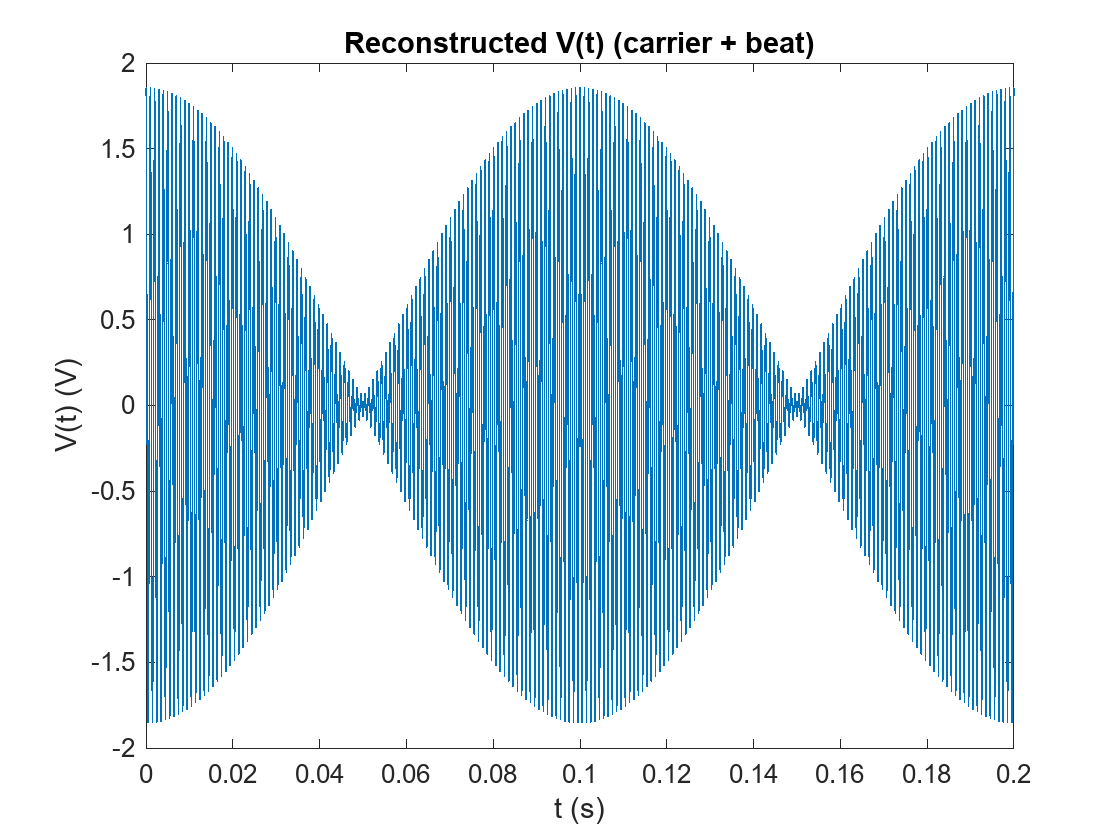

% get phasor at that point
V1h = sol{1}.NodalSolution(nodeIdx);
V2h = sol{2}.NodalSolution(nodeIdx);


% build time vector covering a few beat cycles
beatFreq = abs(f2 - f1);
Tbeat    = 1/beatFreq;
Fs       = 100e3;                     % sampling rate for time-domain
t        = 0 : 1/Fs : 2*Tbeat;        % 2 beat periods

% reconstruct real time-domain signal
Vt = real( V1h*exp(1j*2*pi*f1*t) + V2h*exp(1j*2*pi*f2*t) );
Vt0     = Vt - mean(Vt);           % remove DC
Env     = abs(hilbert(Vt0));      % instantaneous envelope


% --- Plotting ---

% 1) Time series
figure;
plot(t, Vt);
xlabel('t (s)'); ylabel('V(t) (V)');
title('Reconstructed V(t) (carrier + beat)');

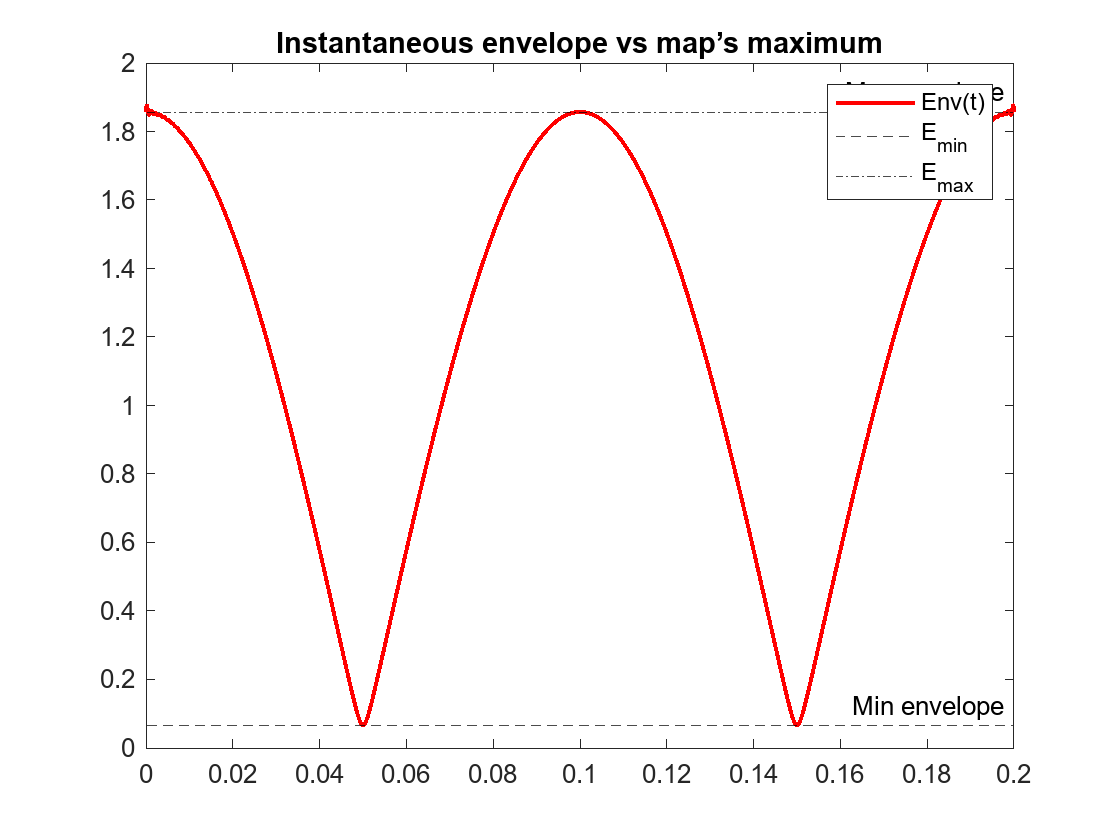

A1 = abs(V1h);
A2 = abs(V2h);
Emin = abs(A1 - A2);
Emax = A1 + A2;
% Peak to peak amplitude and Peak Amplitude ARE NOT THE SAME
figure;
plot(t,Env,'r','LineWidth',1.5);
yline(Emin, 'k--', 'Min envelope');
yline(Emax, 'k-.', 'Max envelope');
hold off;
legend('Env(t)','E_{min}','E_{max}');
title('Instantaneous envelope vs map’s maximum');

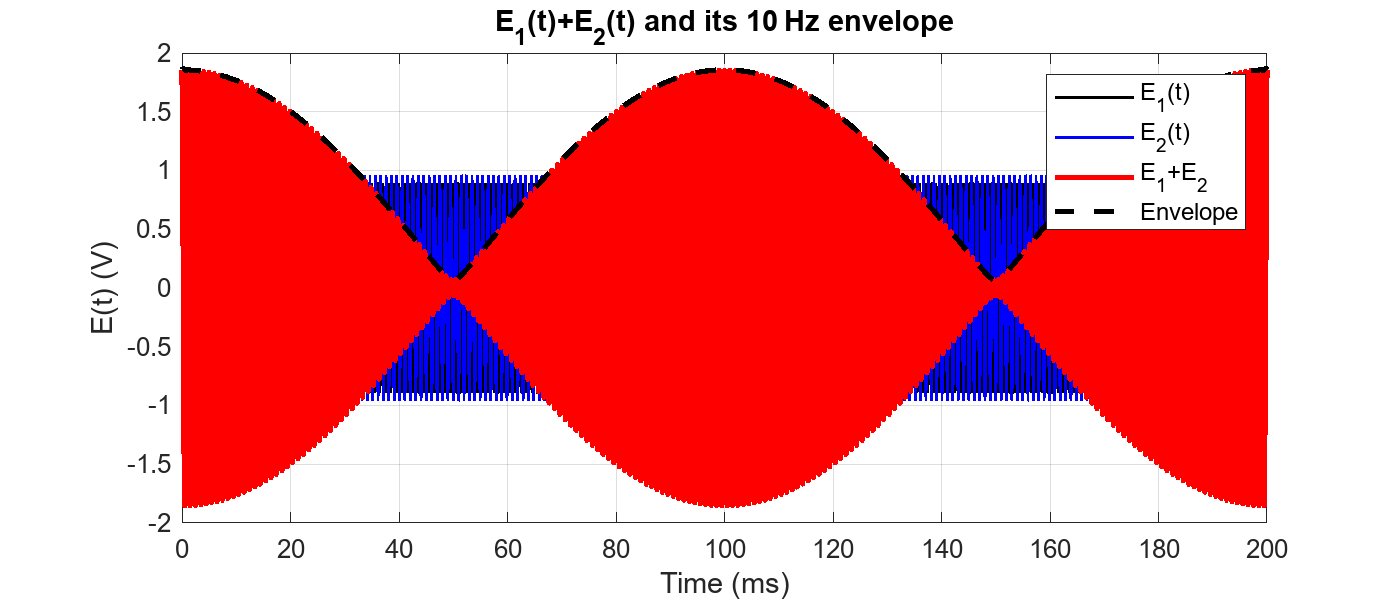

t_end = 200e-3;              % 1 millisecond
Fs    = 200e3;             % 500 kHz sampling to resolve 2 kHz
t     = 0:1/Fs:t_end;    
% 2) Reconstruct each carrier
E1 = real( V1h * exp(1j*2*pi*f1*t) );
E2 = real( V2h * exp(1j*2*pi*f2*t) );

% 3) Sum
Esum = E1 + E2;

% 4) Compute the envelope via Hilbert
Env = abs( hilbert(Esum) );

% 5) Plot
figure('Position',[100 100 700 300]);
plot(t*1e3, E1, 'k-', 'LineWidth',1);      hold on;
plot(t*1e3, E2, 'b-', 'LineWidth',1);
plot(t*1e3, Esum, 'r-', 'LineWidth',2);
plot(t*1e3, Env, 'k--','LineWidth',2);
hold off;

xlim([0 t_end]*1e3);
xlabel('Time (ms)');
ylabel('E(t) (V)');
legend('E_{1}(t)','E_{2}(t)','E_{1}+E_{2}','Envelope','Location','NorthEast');
title('E_{1}(t)+E_{2}(t) and its 10 Hz envelope');
grid on;

u1_abs  = abs(sol{1}.NodalSolution);       % N×1 of |V1| at each node
u2_abs  = abs(sol{2}.NodalSolution);       % N×1 of |V2| at each node

queryPts = centers   % M×2

queryPts =   -24.7500   24.7500
   24.7500   24.7500
   24.7500  -24.7500
  -24.7500  -24.7500
         0   24.7500
  -12.4000   12.3000
   12.3000   12.3000
  -24.7500         0
         0         0
   24.7500         0


% Preallocate array to hold “full‐swing” at each query point:
numPts    = size(queryPts,1);
fullSwing = zeros(numPts,1);

for k = 1:numPts
    xq = queryPts(k,1);
    yq = queryPts(k,2);
    
    % Compute squared distance to every mesh node:
    dist2 = (nodes(1,:) - xq).^2 + (nodes(2,:) - yq).^2;
    
    % Find index of the nearest node:
    [~, idx] = min(dist2);
    
    % Read out |V1| and |V2| at that node, then take the min and double:
    A_node      = min( u1_abs(idx), u2_abs(idx) );
    fullSwing(k)= 2 * A_node;
end

% Build a table with columns x, y, and FullSwing:
T = table( queryPts(:,1), queryPts(:,2), fullSwing, ...
           'VariableNames', {'x','y','FullSwing'} );

% Display it:
disp(T)

      x         y       FullSwing
    ______    ______    _________

    -24.75     24.75     2.9134  
     24.75     24.75     4.7346  
     24.75    -24.75     3.9508  
    -24.75    -24.75     3.1415  
         0     24.75     4.8924  
     -12.4      12.3     2.9134  
      12.3      12.3     4.7346  
    -24.75         0     2.7773  
         0         0     2.5193  
     24.75         0     2.7773  
     -12.4     -12.4     3.1415  
      12.3     -12.4     3.9508  
         0    -24.75     1.9837  



% Suppose you want the value at these query points (M×2):
queryPts = centers

queryPts =   -24.7500   24.7500
   24.7500   24.7500
   24.7500  -24.7500
  -24.7500  -24.7500
         0   24.7500
  -12.4000   12.3000
   12.3000   12.3000
  -24.7500         0
         0         0
   24.7500         0



% Pre‐allocate
M       = size(queryPts,1);
pickedV = zeros(M,1);

% Loop (or vectorized)
for k = 1:M
    xq = queryPts(k,1);
    yq = queryPts(k,2);
    
    % returns the nearest mesh‐node index
    nodeID    = findNodes(mesh,'nearest',[xq; yq]);  
    
    % extract the PP_beat value
    pickedV(k) = PP_beat(nodeID);
end

% display
T = table(queryPts(:,1), queryPts(:,2), pickedV, ...
          'VariableNames',{'x','y','PP_beat'});
disp(T)

      x         y       PP_beat
    ______    ______    _______

    -24.75     24.75    2.9134 
     24.75     24.75    4.7346 
     24.75    -24.75    3.9508 
    -24.75    -24.75    3.1415 
         0     24.75    4.8924 
     -12.4      12.3    2.9134 
      12.3      12.3    4.7346 
    -24.75         0    2.7773 
         0         0    4.7923 
     24.75         0    2.7773 
     -12.4     -12.4    3.1415 
      12.3     -12.4    3.9508 
         0    -24.75    1.9837 

